# **Project 2 - Effectivness of Not Switching Classrooms**

**By Michaela Fox and Elisa Camacho**

## **Question**

Our modeling question is does having students stay in one classroom reduce the number of students that get the common cold as opposed to having students switch classrooms like in most schools? This is a prediction question, because we are trying to predict if a certain way of arranging students will better protect against the common cold. This is interesting because it will help us find a new way of stopping the spread of a disease like the common cold in the school setting. Our model's results will benefit people who work in school districts such as teachers who interact directly with the high schoolers, principals, and the high schooler's family.

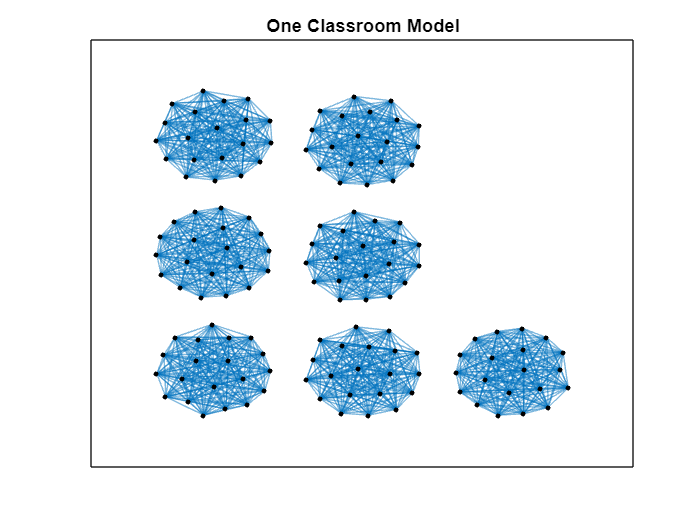

pod20 = ones(20,20) - eye(20);
zeros20 = zeros(20,20);
finalmatrix = [
    pod20 zeros20 zeros20 zeros20 zeros20 zeros20 zeros20;
    zeros20 pod20 zeros20 zeros20 zeros20 zeros20 zeros20;
    zeros20 zeros20 pod20 zeros20 zeros20 zeros20 zeros20;
    zeros20 zeros20 zeros20 pod20 zeros20 zeros20 zeros20;
    zeros20 zeros20 zeros20 zeros20 pod20 zeros20 zeros20;
    zeros20 zeros20 zeros20 zeros20 zeros20 pod20 zeros20;
    zeros20 zeros20 zeros20 zeros20 zeros20 zeros20 pod20];
graph20pod = graph(finalmatrix);
figure();
h = plot(graph20pod, 'NodeColor', 'k', 'LineWidth', 0.1);
layout(h, 'force', 'WeightEffect', 'inverse')
title('One Classroom Model')

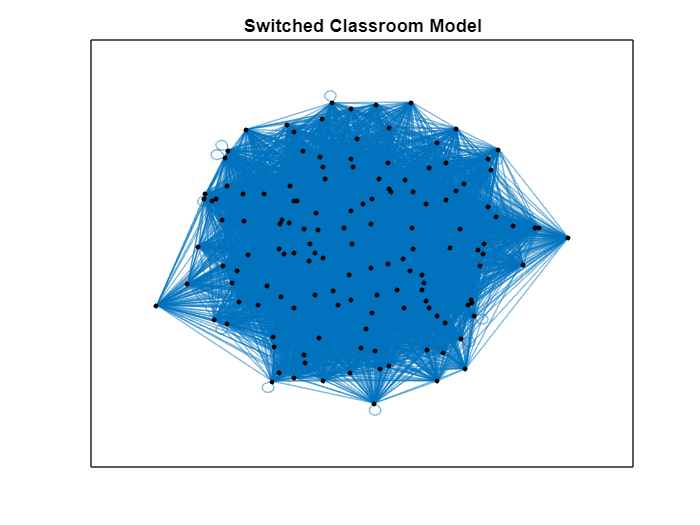

finalmatrix2 = finalmatrix;
rng(0,'twister');
for i = 1:5880
    p1 = randi([1 140]);
    p2 = randi([1 140]);
    finalmatrix2(p1,p2) = finalmatrix2(p1,p2) + 1;
    finalmatrix2(p2,p1) = finalmatrix2(p2,p1) + 1;
end
graph20pod2 = graph(finalmatrix2);
figure();
h = plot(graph20pod2, 'NodeColor', 'k', 'LineWidth', 0.1);
layout(h, 'force', 'WeightEffect', 'inverse')
title('Switched Classroom Model')

%Simulate one classroom model
infectionrate = 0.324;
recoveryrate = 0.143;
iv0 = zeros(140,1);
iv0(1) = 1;
timesteps = 30;
realizations = 5;
simresults1 = zeros(timesteps, realizations);
simresults2 = zeros(timesteps, realizations);
for i = 1:realizations
    [sho,iho,rho] =  simulate_absir(finalmatrix, iv0, timesteps, infectionrate, recoveryrate);
    simresults1(:, i) = sum(iho, 1);
end

simulate_absir is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\mfox\OneDrive - Olin College of Engineering\Modsim
    C:\Users\mfox\OneDrive - Olin College of Engineering\Modsim\Modsim Project 2

Change the MATLAB current folder or add its folder to the MATLAB path.

%Simulate switched classroom model
for s = 1:realizations
    [shs,ihs,rhs] =  simulate_absir(finalmatrix2, iv0, timesteps, infectionrate, recoveryrate);
    simresults2(:,s) = sum(ihs,1);
end
meano = mean(simresults1, 2);
means = mean(simresults2, 2);
%icounto = sum(iho,1);
%icounts = sum(ihs,1);
maxo = max(meano);
maxs = max(means);
figure()
plot(meano, 'c-', 'LineWidth', 2.0, 'DisplayName', 'One Classroom Model');
xlabel('Timestep')
ylabel('Mean Infected Persons')
ylim([0 140])
legend() 
hold on;
plot(means, 'g-', 'LineWidth', 2.0, 'DisplayName', 'Switched Classroom Model');

%heatmap 
figure()
imagesc(finalmatrix);
colorbar
figure()
imagesc(finalmatrix2);
colorbar
%blue is weaker connections and yellow is stronger connections

%parameter sweep

Max_all = zeros(1,100);
numofpeople = zeros(1,100);
for p = 1:100
    pod202 = ones(p,p) - eye(p);
    zeros202 = zeros(p,p);
    finalmatrix202 = [
        pod202 zeros202 zeros202 zeros202 zeros202 zeros202 zeros202;
        zeros202 pod202 zeros202 zeros202 zeros202 zeros202 zeros202;
        zeros202 zeros202 pod202 zeros202 zeros202 zeros202 zeros202;
        zeros202 zeros202 zeros202 pod202 zeros202 zeros202 zeros202;
        zeros202 zeros202 zeros202 zeros202 pod202 zeros202 zeros202;
        zeros202 zeros202 zeros202 zeros202 zeros202 pod202 zeros202;
        zeros202 zeros202 zeros202 zeros202 zeros202 zeros202 pod202];

    infectionrate = 0.324;
    recoveryrate = 0.143;
    iv0 = zeros(p*7,1);
    iv0(1) = 1;
    timesteps2 = 500;
    realizations = 5;
    simresults12 = zeros(timesteps2, realizations);
    for i = 1:realizations
        [sho2,iho2,rho2] =  simulate_absir(finalmatrix202, iv0, timesteps2, infectionrate, recoveryrate);
        simresults12(:, i) = sum(iho2, 1);
    end
    meano = mean(simresults12, 2);
    Max_all(p) = max(meano);
    numofpeople(p) = [p];
end
figure()
title('Different Number of People Per Classroom In One Classroom Model')
plot(numofpeople, Max_all, 'r-', 'LineWidth', 2.0);
xlabel('Pod Size')
ylabel('Max Mean Infected Persons')